# Train SAC Agent for Ball Balance Control

This example shows how to train a soft actor-critic (SAC) reinforcement learning agent to control a robot arm for a ball-balancing task.

## Introduction

The robot arm in this example is a Kinova Gen3 robot, which is a seven degree-of-freedom (DOF) manipulator. The arm is tasked to balance a ping pong ball at the center of a flat surface (plate) attached to the robot gripper. Only the final two joints are actuated and contribute to motion in the pitch and roll axes as shown in the following figure. The remaining joints are fixed and do not contribute to motion.

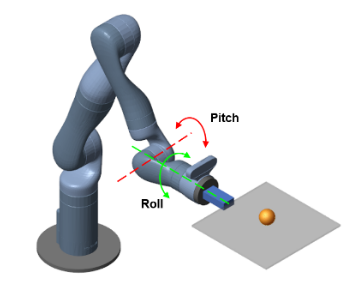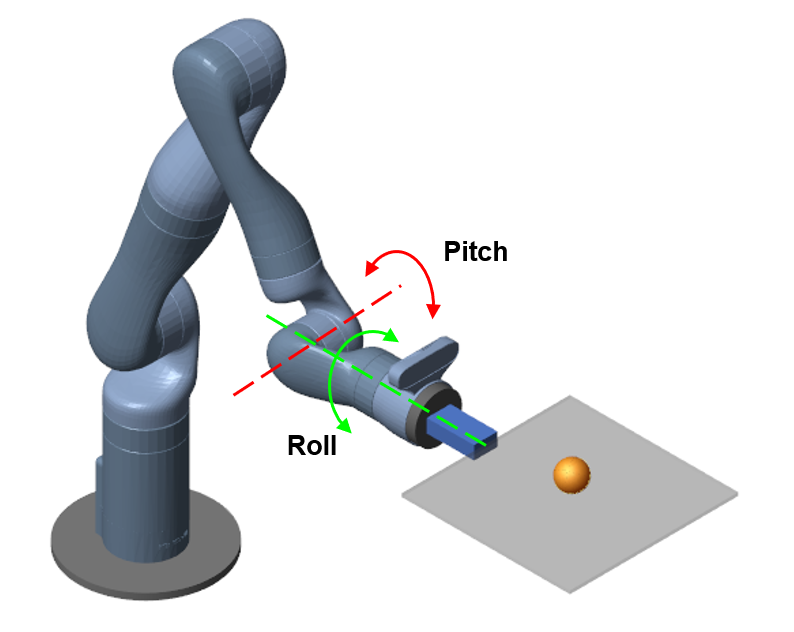

Open the Simulink® model to view the system. The model contains a Kinova Ball Balance subsystem connected to an RL Agent block. The agent applies an action to the robot subsystem and receives the resulting observation, reward, and is-done signals. 

%open_system("rlKinovaBallBalance")

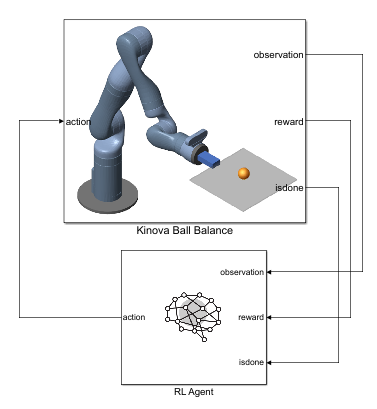

View to the Kinova Ball Balance subsystem.

%open_system("rlKinovaBallBalance/Kinova Ball Balance")

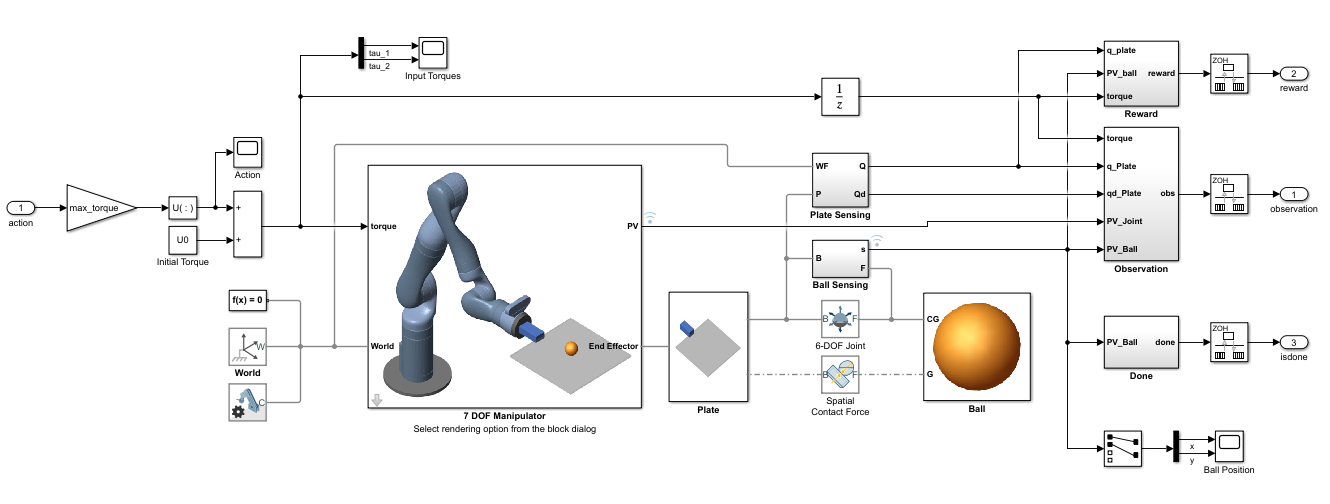

In this model:

- The physical components of the system (manipulator, ball, and plate) are modeled using Simscape™ Multibody™ components.

- The plate is constrained to the end effector of the manipulator.

- The ball has six degrees of freedom and can move freely in space.

- Contact forces between the ball and plate are modeled using the Spatial Contact Force block.

- Control inputs to the manipulator are the torque signals for the actuated joints.

If you have the [Robotics System Toolbox Robot Library Data](https://www.mathworks.com/matlabcentral/fileexchange/98714-robotics-system-toolbox-robot-library-data) support package, you can view a 3-D animation of the manipulator in the Mechanics Explorer. To do so, open the 7 DOF Manipulator subsystem and set its **Visualization** parameter to `3D Mesh`. If you do have the support package installed, set the **Visualization** parameter to `None`. To download and install the support package, use the Add-On Explorer. For more information see [Get and Manage Add-Ons](docid:matlab_env#buytlwx).

Create the parameters for the example by running the `kinova_params` script included with this example. When you have the Robotics System Toolbox Robot Library Data support package installed, this script also adds the necessary mesh files to the MATLAB® path.

kinova_params

## Define Environment

To train a reinforcement learning agent, you must define the environment with which it will interact. For the ball balancing environment:

- The observations are represented by a 22 element vector that contains information about the positions (sine and cosine of joint angles) and velocities (joint angle derivatives) of the two actuated joints, positions (x and y distances from plate center) and velocities (x and y derivatives) of the ball, orientation (quaternions) and velocities (quaternion derivatives) of the plate, joint torques from the last time step, ball radius, and mass.

- The actions are normalized joint torque values.

- The sample time is $T_s =0\ldotp 01s$, and the simulation time is $T_f =10s$.

- The simulation terminates when the ball falls off the plate.

- The reward $r_t$ at time step $t$ is given by:

                
$$\begin{array}{l}
r_t =r_{\textrm{ball}} +r_{\textrm{plate}} +r_{\textrm{action}} \\
r_{\textrm{ball}} =e^{-0\ldotp 001\left(x^2 +y^2 \right)} \\
r_{\textrm{plate}} =-0\ldotp 1\left(\phi^2 +\theta^2 +\psi^2 \right)\\
r_{\textrm{action}} =-0\ldotp 05\left(\tau_1^2 +\tau_2^2 \right)
\end{array}$$


Here, $r_{\textrm{ball}}$ is a reward for the ball moving closer to the center of the plate, $r_{\textrm{plate}}$ is a penalty for plate orientation, and $r_{\textrm{action}}$ is a penalty for control effort. $\phi$, $\theta$, and $\psi$ are the respective roll, pitch, and yaw angles of the plate in radians. $\tau_1$ and $\tau_2$ are the joint torques.

Create the observation and action specifications for the environment using continuous observation and action spaces.

nObs = 30;  % Number of dimension of the observation space
nAct = 4;   % Number of dimension of the action space

obsInfo = rlNumericSpec([nObs 1]);

actInfo = rlNumericSpec([nAct 1]);
actInfo.LowerLimit = -1;
actInfo.UpperLimit = 1;

Create the Simulink environment interface using the observation and action specifications. For more information on creating Simulink environments, see [`rlSimulinkEnv`](docid:rl_ref#mw_12cc40dc-3191-4a23-af71-1625696c1a14).

mdl = "rlKinovaBallBalance";
blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` parameter. 

env.ResetFcn = @kinovaResetFcn;
env.UseFastRestart = 'on';

This reset function (provided at the end of this example) randomly initializes the initial x and y positions of the ball with respect to the center of the plate. For more robust training, you can also randomize other parameters inside the reset function, such as the mass and radius of the ball.

Specify the sample time `Ts` and simulation time `Tf`.

Ts = 0.05;
Tf = 50;

## Create Agent

The agent in this example is a soft actor-critic (SAC) agent. SAC agents use one or two parametrized Q-value function approximators to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter). For more information on SAC agents, see [Soft Actor-Critic Agents](docid:rl_ug#mw_66993d46-0fa5-41fa-9b73-d3caf6f9e649).

The SAC agent in this example uses two critics. To model the parametrized Q-value functions within the critics, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value). For more information on creating deep neural networks for reinforcement learning agents, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

The actor and critic networks are initialized randomly. Ensure reproducibility by fixing the seed of the random generator.

rng(0)

Define each network path as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel.

% Define the network paths.
observationPath = [
    featureInputLayer(nObs,Name="observation")
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(nAct,Name="action");

Assemble `dlnetwork` object.

criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"action","concat/in2");

View the critic neural network.

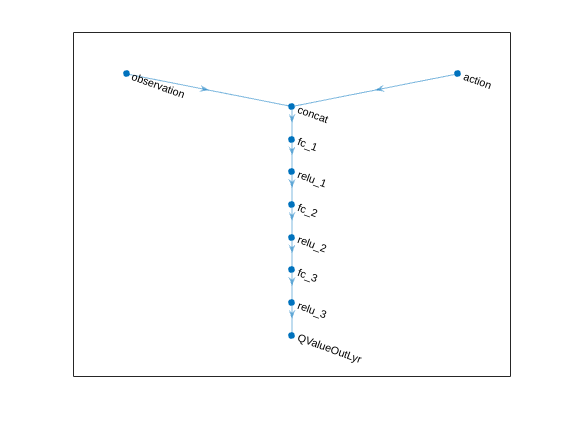

plot(criticNet)

Display the number of weights.

summary(initialize(criticNet))

   Initialized: true

   Number of learnables: 50.1k

   Inputs:
      1   'observation'   30 features
      2   'action'        4 features



Create the critic approximators using `rlQValueFunction`. When using two critics, a SAC agent requires them to have different initial parameters. Initialize the networks separately to make sure that their initial weights are different.

critic1 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation");
critic2 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation");

Soft Actor-critic agents use a parametrized stochastic policy over a continuous action space, which is implemented by a continuous Gaussian actor. 

This actor takes an observation as input and returns as output a random action sampled from a Gaussian probability distribution.

To approximate the mean values and standard deviations of the Gaussian distribution, you must use a neural network with two output layers, each having as many elements as the dimension of the action space. One output layer must return a vector containing the mean values for each action dimension. The other must return a vector containing the standard deviation for each action dimension.

Since standard deviations must be nonnegative, use a softplus or ReLU layer to enforce nonnegativity. The SAC agent automatically reads the action range from the `UpperLimit` and `LowerLimit` properties of `actInfo` (which is used to create the actor), and then internally scales the distribution and bounds the action. Therefore, do not add a `tanhLayer` as the last nonlinear layer in the mean output path.

Define each network path as an array of layer objects, and assign names to the input and output layers of each path.

% Create the actor network layers.
commonPath = [
    featureInputLayer(nObs,Name="observation")
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(64,Name="meanFC")
    reluLayer
    fullyConnectedLayer(nAct,Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(nAct,Name="stdFC")
    reluLayer
    softplusLayer(Name="actionStd")
    ];

Assemble `dlnetwork` object.

actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"commonPath","meanFC/in");
actorNet = connectLayers(actorNet,"commonPath","stdFC/in");

View the actor neural network.

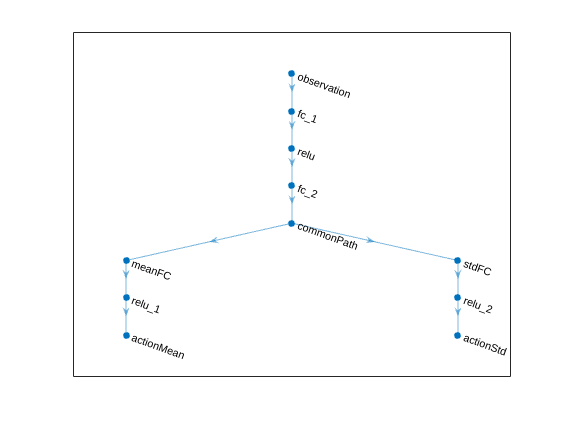

plot(actorNet)

Initialize network and display the number of weights.

actorNet = initialize(actorNet);
summary(actorNet)

   Initialized: true

   Number of learnables: 49.8k

   Inputs:
      1   'observation'   30 features



Create the actor function using `rlContinuousGaussianActor`.

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd");

The SAC agent in this example trains from an experience buffer of maximum capacity 1e6 by randomly selecting mini-batches of size 256. The fact that the discount factor is 0.99, that is very close to 1, means that the agent keeps more into account long term rewards (a discount factor closer to 0 would instead place a heavier discount on future rewards, therefore encouraging short term ones). For a full list of SAC hyperparameters and their descriptions, see [`rlSACAgentOptions`](docid:rl_ref#mw_378cf35c-0c56-448f-a836-4c236af12954).

Specify the agent hyperparameters for training. 

agentOpts = rlSACAgentOptions( ...
    TargetSmoothFactor=1e-3, ...    
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=256, ...
    NumWarmStartSteps=256*50, ...
    DiscountFactor=0.99);

For this example the actor and critic neural networks are updated using the Adam algorithm with a learn rate of 1e-4 and gradient threshold of 1. Specify the optimizer parameters.

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-3;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;

for ct = 1:2
    agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
    agentOpts.CriticOptimizerOptions(ct).LearnRate = 1e-3;
    agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
end

Create the SAC agent.

agent = rlSACAgent(actor,[critic1,critic2],agentOpts);

## Train Agent

To train the agent, first specify the training options using [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0). For this example, use the following options:

- Run each training for at most 6000 episodes, with each episode lasting at most `floor(Tf/Ts)` time steps.

- Stop training when the evaluation of the greedy policy exceeds 700.

- To speed up training set the `UseParallel` option to `true`, which requires Parallel Computing Toolbox™ software. If you do not have the software installed set the option to `false`.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    Plots="training-progress", ...
    SimulationStorageType="file",...
    StopTrainingCriteria="EvaluationStatistic", ...
    StopTrainingValue=7500, ...
    UseParallel=false);

Specify a visualization flag `doViz` that shows animation of the ball in a MATLAB figure. For parallel training, disable all visualization.

if trainOpts.UseParallel
    % Disable visualization in Simscape Mechanics Explorer
    set_param(mdl, SimMechanicsOpenEditorOnUpdate="off");
    set_param(mdl+"/Kinova Ball Balance/7 DOF Manipulator", ...
        "VChoice", "None");
    % Disable animation in MATLAB figure
    doViz = false;
    save_system(mdl);
else
    % Enable visualization in Simscape Mechanics Explorer
    set_param(mdl, SimMechanicsOpenEditorOnUpdate="on");
    % Enable animation in MATLAB figure
    doViz = true;
end

You can log training data to disk using the [`rlDataLogger`](docid:rl_ref#mw_3de067fc-ffdf-45f9-9a2b-439d9463a9cc) function. For this example, log the episode experience and actor and critic function losses. The functions `logAgentLearnData` and `logEpisodeData` are defined at the end of this Live Script. For more information see [Log Training Data To Disk](docid:rl_ug#mw_19d564c5-28d0-4c88-9bc5-64ac788f2116).

% logger = rlDataLogger();
% logger.AgentLearnFinishedFcn = @logAgentLearnData;
% logger.EpisodeFinishedFcn    = @(data) logEpisodeData(data, doViz);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining
    % Evaluate the performance of the greedy policy every 25 training
    % episodes, averaging the cumulative reward of 5 simulations.
    evaluator = rlEvaluator(EvaluationFrequency=25,NumEpisodes=5);
    % train
    % trainResult = train(agent,env,trainOpts,Logger=logger,Evaluator=evaluator);
    trainResult = train(agent,env,trainOpts,Evaluator=evaluator);
    save("trained_agents/kinovaBallBalanceAgent_with_mars_rover_fluent_v1.mat", "agent");
else

    load("trained_agents/kinovaBallBalanceAgent_with_mars_rover_act2_act3_v3.mat");
end

Invalid or deleted object.

Error in rl.internal.episodeManager.OnlineEpisodeManager/step (line 196)
            if ~this.IsClosed

Error in rl.internal.trainmgr.OnlineTrainingManager>@(info)step(tmon,info) (line 106)
   

A snapshot of training progress is shown in the following figure. You can expect different results due to randomness in the training process.

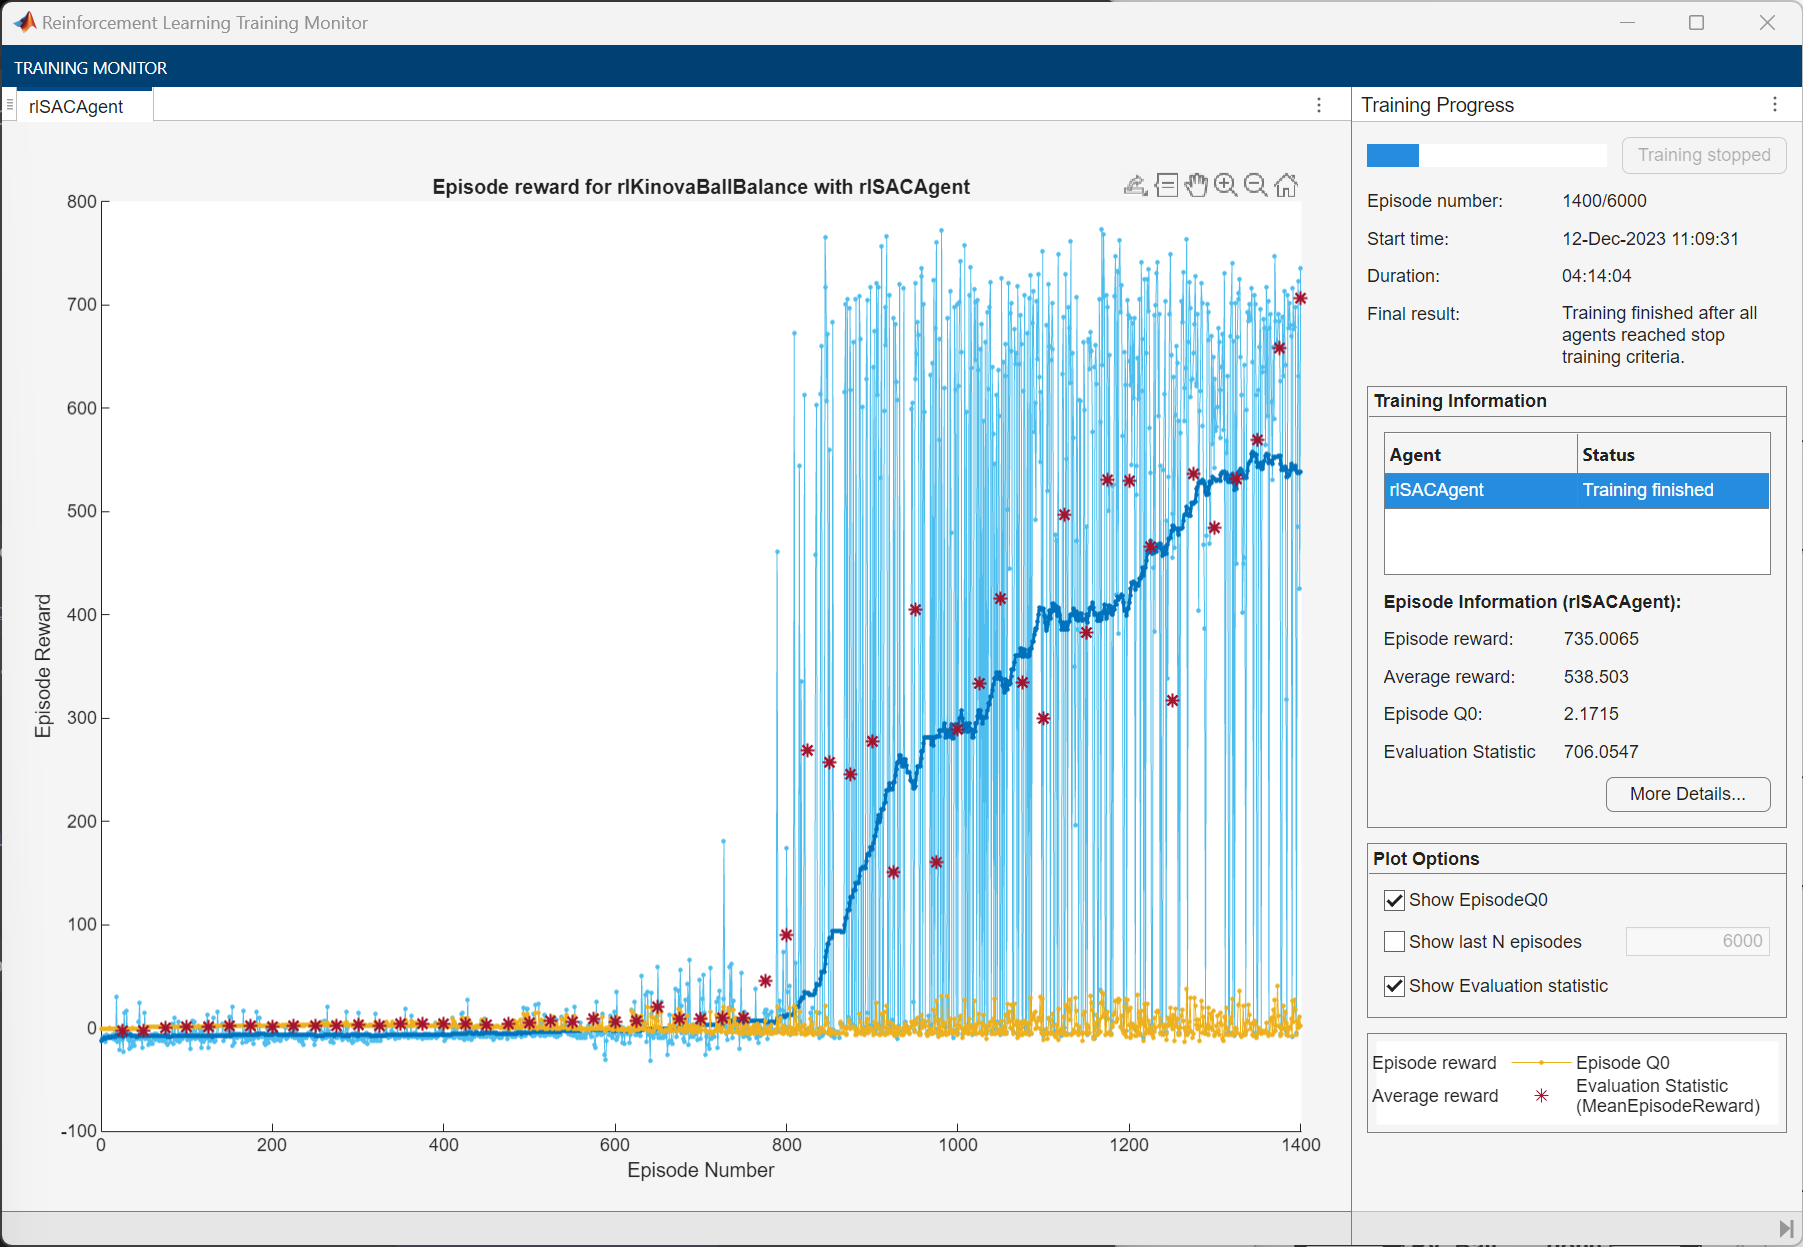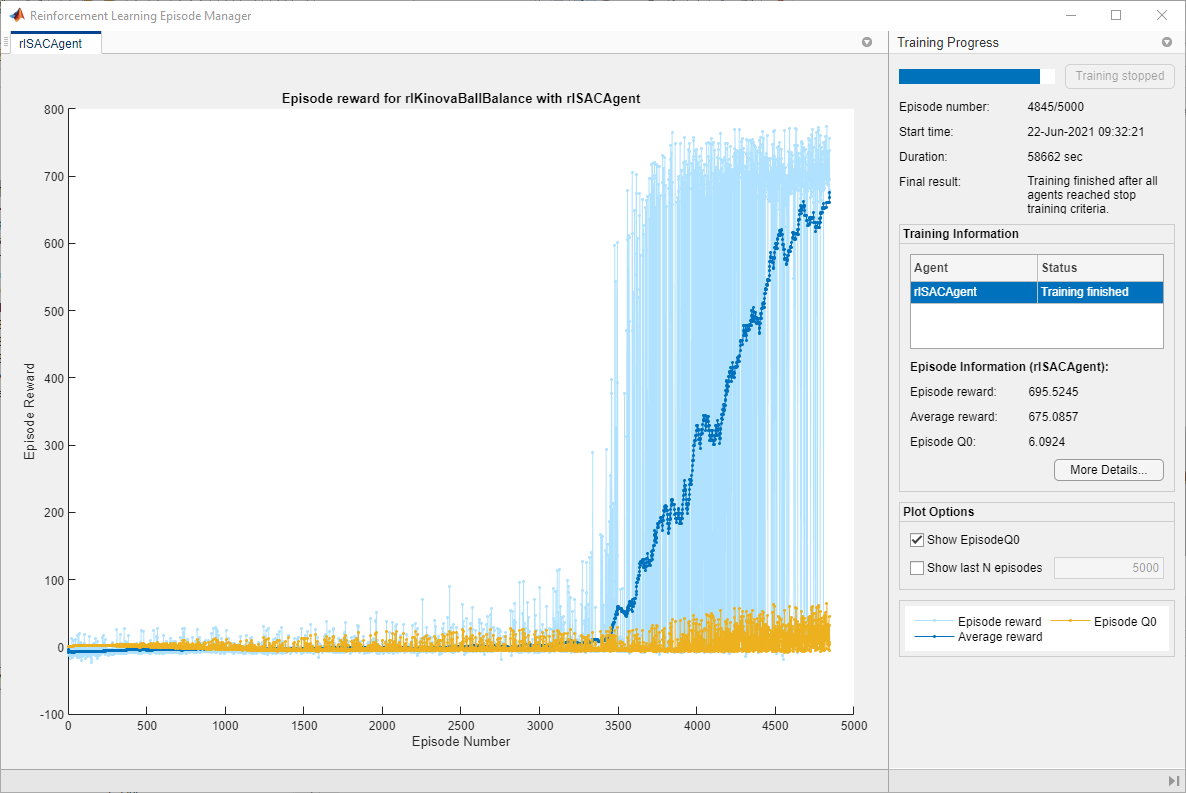

## Simulate Trained Agent

Specify an initial position for the ball with respect to the plate center. To randomize the initial ball position during simulation, set the `userSpecifiedConditions` flag to `false`.

userSpecifiedConditions = false;
if userSpecifiedConditions
    ball.x0 = 0.075;
    ball.y0 = -0.075;
    env.ResetFcn = [];
else
    env.ResetFcn = @kinovaResetFcn;
end

Create a simulation options object for configuring the simulation. The agent will be simulated for a maximum of `floor(Tf/Ts)` steps per simulation episode.

simOpts = rlSimulationOptions(MaxSteps=floor(Tf/Ts));

Enable visualization during simulation.

set_param(mdl, SimMechanicsOpenEditorOnUpdate="on");
doViz = true;

Simulate the agent using the greedy policy.

agent.UseExplorationPolicy = false;
experiences = sim(agent,env,simOpts);

View the trajectory of the ball using the Ball Position scope block.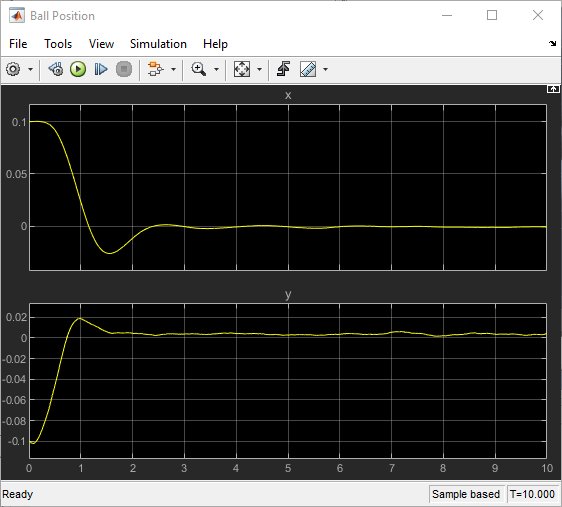

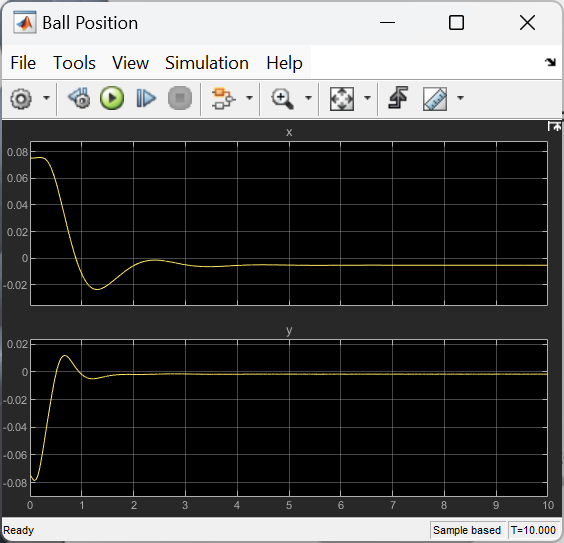

View the animation of the ball on the plate in a MATLAB figure.

fig = animatedPath(experiences);

## Environment Reset Function

function in = kinovaResetFcn(in)
    persistent all_paths
    if isempty(all_paths)
        data = load('data/rover_paths.mat');
        pathNames = fieldnames(data);
        all_paths = cell(size(pathNames));
        for i = 1:numel(pathNames)
            all_paths{i} = data.(pathNames{i});
        end
    end

    % Выбор случайного маршрута
    idx = randi(numel(all_paths));
    % idx=19;
    selected_path = all_paths{idx};

    % Явное преобразование в double (в случае struct → Simulink)
    % rover_path.x = double(selected_path.x(:));
    % rover_path.y = double(selected_path.y(:));
    % rover_path.z = double(selected_path.z(:));
    % rover_path.Offset_vis_z = double(selected_path.Offset_vis_z);
    % rover_path.t0.yaw   = double(selected_path.t0.yaw);
    % rover_path.t0.pitch = double(selected_path.t0.pitch);
    % rover_path.t0.roll  = double(selected_path.t0.roll);
    % rover_path.t0.pzOffset = double(selected_path.t0.pzOffset);

    % Передача в Reinforcement Learning environment
    in = setVariable(in, "rover_path", selected_path);
    %rover_path.t0.pzOffset = double(selected_path.z(idx)) - 1.3;
    %rover_path.t0.pitch = 0.0;
    %rover_path.t0.roll  =  0.0;
    rover_path.name = selected_path.name;

    
    % (для отладки)
    assignin('base', 'rover_path_debug', rover_path);
    % --- Остальное: настройки шара ---
    ball.radius = 0.02;
    ball.mass   = 0.0027;
    ball.shell  = 0.0002;
    ball.moi = calcMOI(ball.radius, ball.shell, ball.mass);

    ball.x0  = -0.1 + 0.2*rand;
    ball.y0  = -0.1 + 0.2*rand;
    ball.z0  = ball.radius;
    ball.dx0 = 0;
    ball.dy0 = 0;
    ball.dz0 = 0;

    ball.staticfriction     = 0.5;
    ball.dynamicfriction    = 0.3;
    ball.criticalvelocity   = 1e-3;

    coeff_restitution = 0.89;
    [k, c, w] = cor2SpringDamperParams(coeff_restitution, ball.mass);
    ball.stiffness = k;
    ball.damping = c;
    ball.transitionwidth = w;

    in = setVariable(in, "ball", ball);

    % --- Случайные углы сочленений ---
    R2_q0 = deg2rad(20) + deg2rad(-5 + 10*rand); 
    R3_q0 = deg2rad(0) + deg2rad(-5 + 10*rand); 
    R6_q0 = deg2rad(-65) + deg2rad(-5 + 10*rand);
    R7_q0 = deg2rad(-90) + deg2rad(-5 + 10*rand);
    in = setVariable(in, "R2_q0", R2_q0);
    in = setVariable(in, "R3_q0", R3_q0);
    in = setVariable(in, "R6_q0", R6_q0);
    in = setVariable(in, "R7_q0", R7_q0);

    m2 = 0.206679;
    m3 = 0.137977;       % масса локтя
    m4 = 0.4;
    
    g = 9.80665;
    m_eff_shoulder = m2 + m3 + m4 + ball.mass;
    d_eff = 0.2;
    shoulder_torque_0 = m_eff_shoulder * g * d_eff * cos(R2_q0);
    
    % shoulder_torque_0 = m2 * g * d2 * cos(R2_q0);    

    m_eff_elbow = m4 + ball.mass;   % всё, что висит на локте
    d_eff_elbow = 0.12;         % расстояние от локтя до центра масс платформы
    elbow_torque_0 = m_eff_elbow * g * d_eff_elbow * cos(R2_q0 + R3_q0);
    
    % elbow_torque_0 = m3 * g * d3 * cos(R2_q0 + R3_q0);

    wrist_torque_0 = (-1.882 + ball.x0 * ball.mass * g) * cos(deg2rad(-65) - R6_q0);
    hand_torque_0 = (0.0002349 - ball.y0 * ball.mass * g) * cos(deg2rad(-90) - R7_q0);
    U0 = [shoulder_torque_0 elbow_torque_0 wrist_torque_0 hand_torque_0];
    in = setVariable(in, "U0", U0);
end


## Data Logging Functions

function dataToLog = logAgentLearnData(data)
% This function is executed after completion
% of the agent's learning subroutine

dataToLog.ActorLoss = data.ActorLoss;
dataToLog.CriticLoss = data.CriticLoss;
end

function dataToLog = logEpisodeData(data, doViz)
% This function is executed after the completion of an episode

dataToLog.Experience = data.Experience;

% Show an animation after episode completion
if doViz
    animatedPath(data.Experience);
end
end

*Copyright 2021-2024 The MathWorks, Inc.*